clear
close all

# **Power analysis for studying variance**

**Shinya M and Takiyama K**

"Guidelines for balancing the number of trials and the number of subjects to ensure the statistical power to detect variability – Implication for gait studies"

**J Biomech.** 2024 Feb 15:165:111995. DOI: [10.1016/j.jbiomech.2024.111995](https://doi.org/10.1016/j.jbiomech.2024.111995)

## **Comparing variance between groups of subjects: an independent-samples design**

As the simplest research framework, we consider comparing the variance of a single variable between two participant groups. An example of studies with such a framework is a research comparing step variability during walking between young and old adult groups. In such studies, what combination of trial number and participant number would ensure an adequate statistical power?

## **Assumption and theory**

We assume that data in each trial follows normal distribution specific to each participant or condition.


$$x_{{\left(subject,condition\right)}} =\mu_{{\left(subject,condition\right)}} +\epsilon$$



$$\epsilon \sim \mathrm{N}{\left(0,{\sigma^2 }_{{\left(\mathrm{s}\mathrm{u}\mathrm{b}\mathrm{j}\mathrm{e}\mathrm{c}\mathrm{t},\mathrm{ }\mathrm{c}\mathrm{o}\mathrm{n}\mathrm{d}\mathrm{i}\mathrm{t}\mathrm{i}\mathrm{o}\mathrm{n}\right)}} \right)}$$


Based on the assumption, the unbiased variance, calculated from the  trials, is related to a chi-squared distribution with $n-1$ degrees of freedom.


$$\chi_{n-1}^2 \sim \frac{{\left(n-1\right)}s^2 }{\sigma^2 }$$


or,


$$\frac{s^2 }{\sigma^2 }\sim \frac{\chi_{n-1}^2 }{{\left(n-1\right)}}$$


Samples that follow the above distribution with sample sizes $N_1$ and $N_2$ would be compared using the non-parametric Mann-Whitney U test to test the difference between independent groups. Once we assume population variances for Group 1 and 2, the probability $1-\beta$ of correctly detecting the difference as statistically significant using the Mann-Whitney U test, is determined with given number of trials $n_1 ,n_2$ and number of participants $N_1 ,N_2$.

## **Simulation parameters**

We calculate the probability 1-β of correctly detecting the difference in variance between groups for given numbers of trials and participants. As an alternative hypothesis, we assumed the population variances for 2 groups.

% number of trials, number of subjects
nTrial1 = 60 ;
nTrial2 = 60 ;
nSubjectGroup1 = 20 ;
nSubjectGroup2 = 20 ;

% population variances for each group
sigma1Squared = 1.0 ;    
sigma2Squared = 1.2 ; 

% parameters for Mann-Whitney U test
alpha = 0.05 ;
tail = 'both' ; % 'both', 'left', or 'right'

% number of simulation
nSim = 10000 ;


In the manuscript, the following parameters were used. The subscript numbers denote the values for each group.

- Numbers of trials:  $n_1 =100,n_2 =20$

- Numbers subjects: $N_1 =20,N_2 =10$

- Population variances: $\sigma_1^2 =2.0, \sigma_2^2 =3.0$

- Siginificance level: $\alpha =0.05$

## **Simulation - a single case**

This is a simulation of one experiment to compare the sample variance between two independent groups.Whether we have a significant difference or not is stochastically determined.

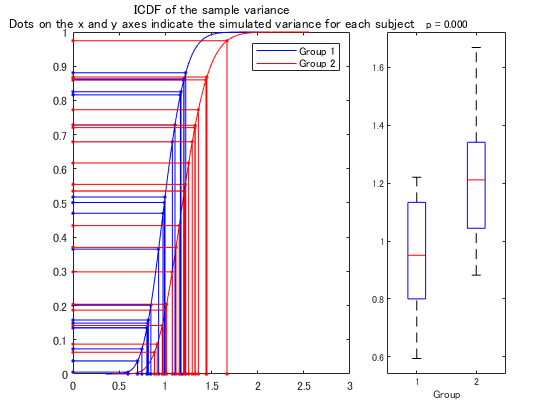

% simulate an experiment

% Create tables of inverse cumulative distribution function of chi-squared distribution
sizeTable = 1000000 ;
pp = linspace(1/sizeTable, 1-1/sizeTable, sizeTable)' ;

distTable1 = chi2inv(pp, nTrial1-1) ;
distTable2 = chi2inv(pp, nTrial2-1) ;

% Create tables of sample variance for each group
randDataGroup1 = distTable1 * sigma1Squared / (nTrial1-1) ;
randDataGroup2 = distTable2 * sigma2Squared / (nTrial2-1) ;

% Simulate one experiment
randIndGroup1 = randi(sizeTable, nSubjectGroup1, 1) ;
simDataGroup1 = randDataGroup1(randIndGroup1) ;

randIndGroup2 = randi(sizeTable, nSubjectGroup2, 1) ;
simDataGroup2 = randDataGroup2(randIndGroup2) ;

% statistical test to compare between the groups
[p, h] = ranksum(simDataGroup1, simDataGroup2) ;


% visualize the simulation
figure(1) ; subplot(1,3,1:2) ;
plot(randDataGroup1, pp, 'b') ; hold on
plot(randDataGroup2, pp, 'r') ;
for ii = 1:length(randIndGroup1)
    xx = [0, randDataGroup1(randIndGroup1(ii)), randDataGroup1(randIndGroup1(ii))] ;
    yy = [pp(randIndGroup1(ii)), pp(randIndGroup1(ii)), 0] ;
    plot(xx, yy, 'b.-')
end
for ii = 1:length(randIndGroup2)
    xx = [0, randDataGroup2(randIndGroup2(ii)), randDataGroup2(randIndGroup2(ii))] ;
    yy = [pp(randIndGroup2(ii)), pp(randIndGroup2(ii)), 0] ;
    plot(xx, yy, 'r.-')
end
legend({'Group 1', 'Group 2'}) ;
title({'ICDF of the sample variance';
       'Dots on the x and y axes indicate the simulated variance for each subject'})

subplot(1,3,3) ;
boxplot([simDataGroup1; simDataGroup2], [ones(size(simDataGroup1)); 2*ones(size(simDataGroup2))]) ; 
xlabel Group
title(sprintf('p = %0.3f', p))

## **Simulation - a post hoc power analysis**

We will repeat many simulations to count the cases where we have a significant difference. The proportion of the case over the total number of simulations can be regarded as statistical power $1-\beta$.

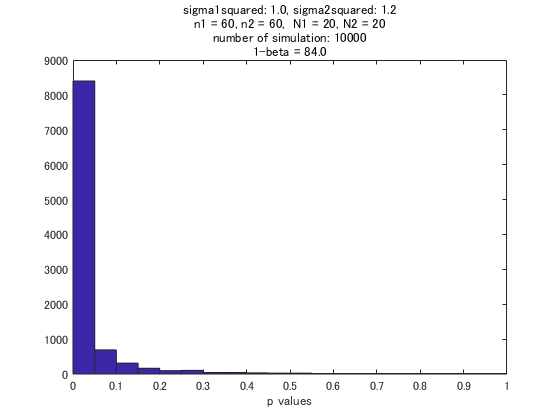

経過時間は 0.999429 秒です。




tic ; % just for monitoring the computational load 

% create simulated data (i.e., sample variances)
randIndGroup1 = randi(sizeTable, nSubjectGroup1, nSim) ;
simDataGroup1 = randDataGroup1(randIndGroup1) ;
randIndGroup2 = randi(sizeTable, nSubjectGroup2, nSim) ;
simDataGroup2 = randDataGroup2(randIndGroup2) ;

% statistical test
for iSim = 1:nSim
    [p, h] = ranksum(simDataGroup1(:,iSim), simDataGroup2(:,iSim), 'alpha', alpha, 'tail', tail) ;
    pArray(iSim) = p ;
    hArray(iSim) = h ;
end

% visulization of the calculated statical power
figure ;
hist(pArray, 20)
statisticalPower = sum(hArray) / nSim * 100 ;
titleText = {sprintf('sigma1squared: %0.1f, sigma2squared: %0.1f', sigma1Squared, sigma2Squared) ;...
             sprintf('n1 = %d, n2 = %d,  N1 = %d, N2 = %d', nTrial1, nTrial2, nSubjectGroup1, nSubjectGroup2);...
             sprintf('number of simulation: %d', nSim) ;...
             sprintf('1-beta = %0.1f', statisticalPower)} ;
title(titleText) ;
xlabel('p values')

toc